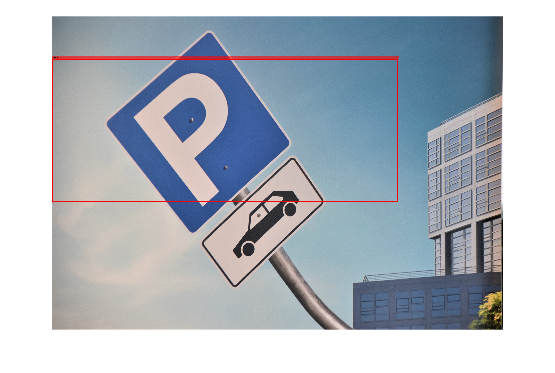

% Load the YOLOv4 detector model
load("aug4signs_yolov4_50e_n3.mat");

% Prompt the user to select an image file
% [fileName, filePath] = uigetfile({'*.jpg;*.png;*.jpeg;*.bmp', 'Image Files (*.jpg, *.png, *.jpeg, *.bmp)'}, 'Select an Image File');
% if fileName == 0
%     % User canceled the file selection
%     disp('No image selected. Exiting.');
%     return;
% end

% Construct the full path to the selected image
selectedImagePath = fullfile(filePath, fileName);

% Read the selected image
I = imread(selectedImagePath);

% Detect objects in the selected image
[bboxes, scores, labels] = detect(detector, I, 'Threshold', 0.01);

% Perform Non-Maximum Suppression (NMS)
overlapThreshold = 0.9; % Adjust this threshold as needed

% Compute overlap ratios
overlapRatios = bboxOverlapRatio(bboxes, bboxes);

% Exclude self-overlaps by setting diagonal elements to zero
overlapRatios(1:length(bboxes) + 1:end) = 0;

% Find indices of boxes to keep using NMS
selectedIndices = find(max(overlapRatios, [], 2) < overlapThreshold);

% Select only the bounding boxes that survived NMS
bboxes = bboxes(selectedIndices, :);
scores = scores(selectedIndices);
labels = labels(selectedIndices);

% Insert object annotations and display the result
detectedImg = insertObjectAnnotation(I, 'Rectangle', bboxes, labels, 'LineWidth', 12, 'FontSize', 18, 'Color', 'red');
figure
imshow(detectedImg);